dir_input = 'C:\Users\rsarin\Desktop\EMG Research\Day 17\';
fname_input = '-allfeatures'; %Tag for file name (follows subject name)

## Run classification

traindata = splitvars(traindata); %split subvariables into independent variable to not anger the classifier.

fprintf(strcat('Classifying _',condnames{1}, ' and _', condnames{2},' \n'))

Classifying _3digit and _cilinder 


% Predictors are features
predictorNames = traindata.Properties.VariableNames(3:end); %This selects all but first two (assumed to be labels and orig index number, fix if this is not the case, or you can manually select here)
predictors = traindata(:,predictorNames); %This
response = traindata(:,'labels'); %labels
imbalancedcostmatrix.ClassNames = unique(response{:,1}); 
imbalancedcostmatrix.ClassificationCosts =  [0 sum(traindata.labels == imbalancedcostmatrix.ClassNames(2)); sum(traindata.labels == imbalancedcostmatrix.ClassNames(1)) 0];
%imbalancedcostmatrix.ClassificationCosts
% trainedClassifier = fitcsvm(predictors, ...
%     response, ...
%     'KernelFunction', 'Linear', ...
%     'Standardize',true);%,...  
    %'Prior','empirical');%,...
    %'Cost',imbalancedcostmatrix );  % Rows are true for cost matrix
   
trainedClassifier = fitcecoc(predictors,response);
%'OutlierFraction',0.15,...

% k-fold cross validation
kval = 5;%min(5,height(response)-2); %Choose number of folds. You can also just set this manually.
cpart = cvpartition(response{:,1},'KFold',kval); % k-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',cpart);
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
     
% Cross validation output
validationAccuracy = 1 - kfoldLoss(partitionedModel);%, 'LossFun', 'ClassifError');
fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 40.34%


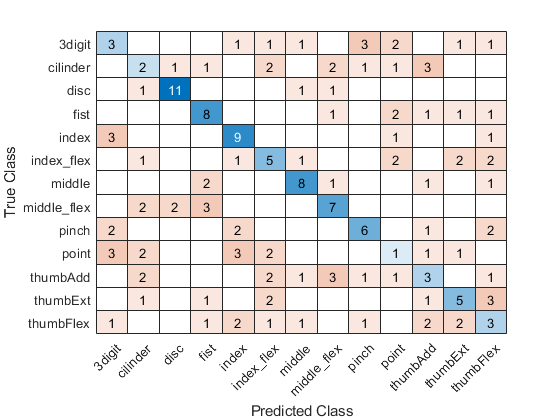

trainconchart = confusionchart(traindata.labels,validationPredictions);

% ,'Normalization','row-normalized'
% 
trainconchart.NormalizedValues

ans =      3     0     0     0     1     1     1     0     3     2     0     1     1
     0     2     1     1     0     2     0     2     1     1     3     0     0
     0     1    11     0     0     0     1     1     0     0     0     0     0
     0     0     0     8     0     0     0     1     0     2     1     1     1
     3     0     0     0     9     0     0     0     0     1     0     0     1
     0     1     0     0     1     5     1     0     0     2     0     2     2
     0     0     0     2     0     0     8     1     0     0     1     0     1
     0     2     2     3     0     0     0     7     0     0     0     0     0
     2     0     0     0     2     0     0     0     6     0     1     0     2
     3     2     0     0     3     2     0     0     0     1     1     1     0



Test accuracy = 43.10%


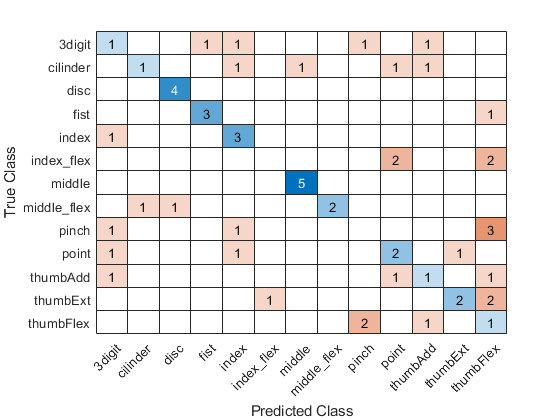

ans =      1     0     0     1     1     0     0     0     1     0     1     0     0
     0     1     0     0     1     0     1     0     0     1     1     0     0
     0     0     4     0     0     0     0     0     0     0     0     0     0
     0     0     0     3     0     0     0     0     0     0     0     0     1
     1     0     0     0     3     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     2     0     0     2
     0     0     0     0     0     0     5     0     0     0     0     0     0
     0     1     1     0     0     0     0     2     0     0     0     0     0
     1     0     0     0     1     0     0     0     0     0     0     0     3
     1     0     0     0     1     0     0     0     0     2     0     1     0



if dotrainandtest
    testdata = splitvars(testdata); %split subvariables into variables
    
    % Code for prediction of test data (stored here for later)
    [predictedlabel,score] = predict(trainedClassifier,testdata(:,predictorNames));
    testAccuracy = sum(testdata.labels==predictedlabel)./length(testdata.labels);
    fprintf('\nTest accuracy = %.2f%%\n', testAccuracy*100);
    figure;
    testconchart = confusionchart(testdata.labels,predictedlabel);%,'Normalization','row-normalized'
    testconchart.NormalizedValues
end

%channel subset selection code
originalEEGdata = EEG.data; %save original EEG data for future reference
channelsubset = 1:2; %change this to select any particular subset of channels
EEG.data = EEG.data(channelsubset,:,:); %keep only the EEG data for the channel subset
EEG.chanlocs.labels = EEG.chanlocs.labels(channelsubset,:); % keep labels of the EEG data from channel subset
